# Train Reinforcement Learning Agent in Basic Grid World

Exemplo testado no Matlab 2020a.

This example shows how to solve a grid world environment using reinforcement learning by training Q-learning and SARSA agents. For more information on these agents, see [Q-Learning Agents](docid:rl_ug#mw_0264db4d-9787-425a-8f8a-1426e5639719) and [SARSA Agents](docid:rl_ug#mw_b47b5155-a09e-4adf-81ed-7a5795fd2bd2).

This grid world environment has the following configuration and rules:

- The grid world is 5-by-5 and bounded by borders, with four possible actions (North = 1, South = 2, East = 3, West = 4).

- The agent begins from cell [2,1] (second row, first column).

- The agent receives a reward +10 if it reaches the terminal state at cell [5,5] (blue).

- The environment contains a special jump from cell [2,4] to cell [4,4] with a reward of +5.

- The agent is blocked by obstacles (black cells).

- All other actions result in –1 reward.

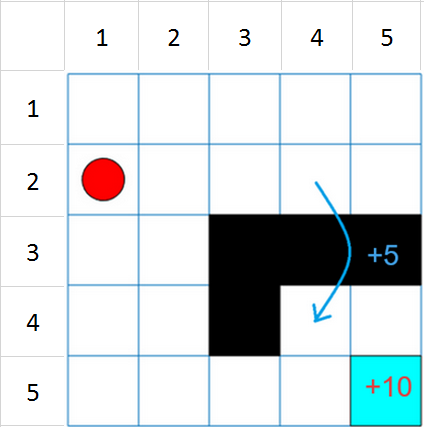

## **Create Grid World Environment**

Create the basic grid world environment.

clear
env = rlPredefinedEnv("BasicGridWorld");    % carrega ambiente predefinido

To specify that the initial state of the agent is always [2,1], create a reset function that returns the state number for the initial agent state. This function is called at the start of each training episode and simulation. States are numbered starting at position [1,1]. The state number increases as you move down the first column and then down each subsequent column. Therefore, create an anonymous function handle that sets the initial state to `2`.

env.ResetFcn = @() 2;                       % funcao anonima que retorna a posicao de reinicio do ambiente

Fix the random generator seed for reproducibility.

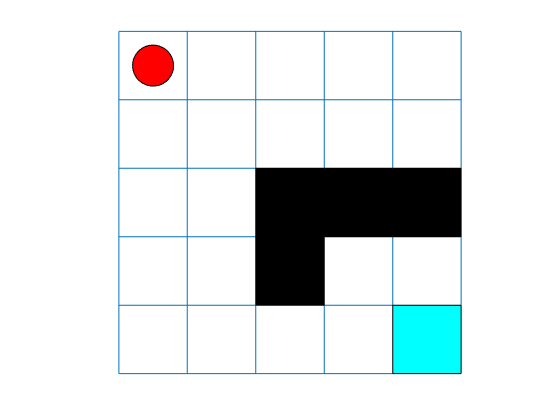

rng(0)                                      % definindo semente de numeros aletorios para reproducibilidade

plot(env)                                   % exibe o ambiente

## **Create Q-Learning Agent**

To create a Q-learning agent, first create a Q table using the observation and action specifications from the grid world environment. Set the learning rate of the representation to 1.

qTable = rlTable(getObservationInfo(env),getActionInfo(env));                                   % cria (instancia) objeto da tabela da funcao value
qRepresentation = rlQValueRepresentation(qTable,getObservationInfo(env),getActionInfo(env));    % monta representacao da funcao value com a tabela
qRepresentation.Options.LearnRate = 1;                                                          % taxa de aprendizado


Next, create a Q-learning agent using this table representation and configure the epsilon-greedy exploration. For more information on creating Q-learning agents, see [`rlQAgent`](docid:rl_ref#mw_b6721f63-a5be-47ea-9325-78f7b379ae30) and [`rlQAgentOptions`](docid:rl_ref#mw_383e9fbf-e99d-4af3-b250-49c6c4ae6f3f).

agentOpts = rlQAgentOptions;                                                                    % cria objeto de opcoes de agente
agentOpts.EpsilonGreedyExploration.Epsilon = .04;                                               % taxa de exploracao inicial em 4%
qAgent = rlQAgent(qRepresentation,agentOpts);                                                   % cria objeto agente

## **Train Q-Learning Agent**

To train the agent, first specify the training options. For this example, use the following options:

- Train for at most 200 episodes. Specify that each episode lasts for most 50 time steps.

- Stop training when the agent receives an average cumulative reward greater than 10 over 30 consecutive episodes.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

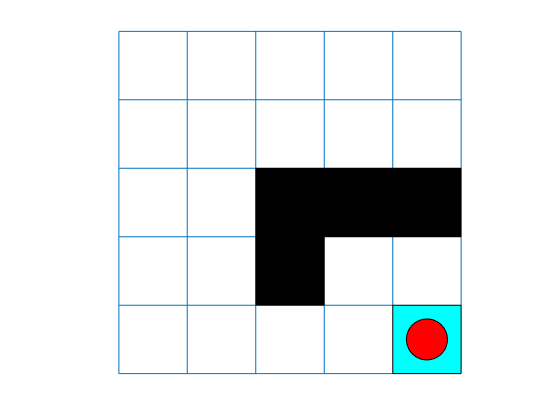

trainOpts = rlTrainingOptions;                      % cria objeto de opcoes de treinamento                 
trainOpts.MaxStepsPerEpisode = 50;                  % maximo de 50 movimentos por episodio
trainOpts.MaxEpisodes= 200;                         % treino por 200 episodios
trainOpts.StopTrainingCriteria = "AverageReward";   % termino por media de recompensa
trainOpts.StopTrainingValue = 11;                   % valor de recompensa media para termino
trainOpts.ScoreAveragingWindowLength = 30;          % intervalo para calculo da media


doTraining = true;
if doTraining
    % Train the agent.
    trainingStats = train(qAgent,env,trainOpts);
else
    % Load the pretrained agent for the example.
    load('basicGWQAgent.mat','qAgent')
end

## **Validate Q-Learning Results**

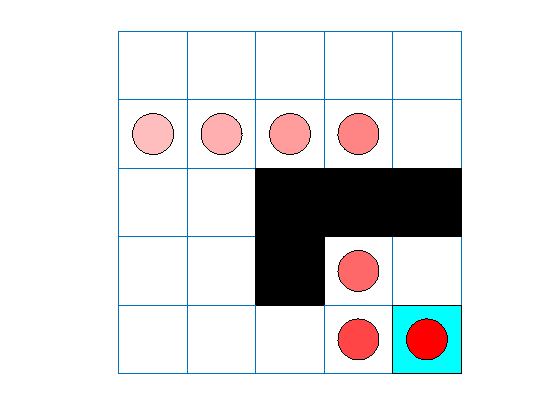

figure
plot(env)
env.Model.Viewer.ShowTrace = true;
env.Model.Viewer.clearTrace;

sim(qAgent,env)